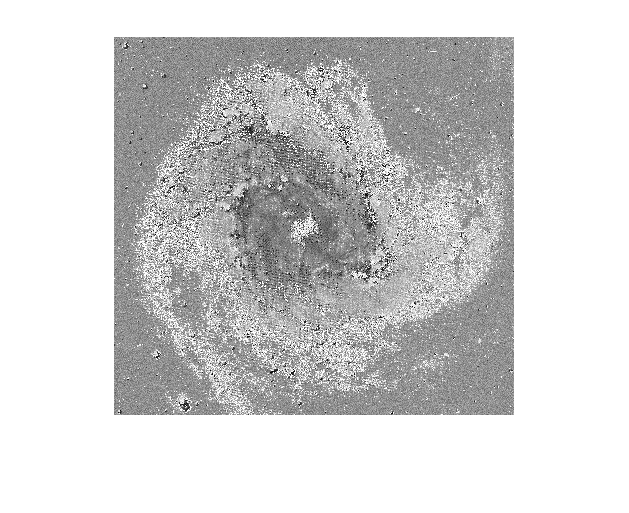

%ques. 8 performing gaussian blur on an image
%Read image
Img = imread('C:\Users\tvasu\Downloads\m83.tif');
A = imnoise(Img,'Gaussian',0.04,0.003);
%Image with noise
figure,imshow(A);

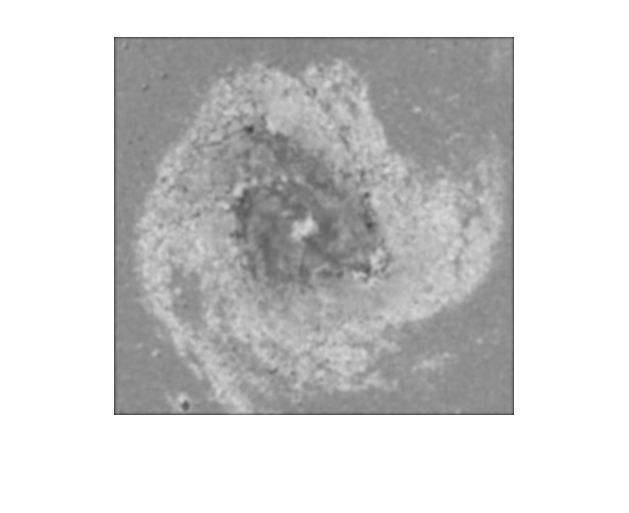

I = double(A);

%Design the Gaussian Kernel
%Standard Deviation
sigma = 1.76;
%Window size
sz = 4;
[x,y]=meshgrid(-sz:sz,-sz:sz);

M = size(x,1)-1;
N = size(y,1)-1;
Exp_comp = -(x.^2+y.^2)/(2*sigma*sigma);
Kernel= exp(Exp_comp)/(2*pi*sigma*sigma);
 %Initialize
Output=zeros(size(I));
%Pad the vector with zeros
I = padarray(I,[sz sz]);

%Convolution
for i = 1:size(I,1)-M
    for j =1:size(I,2)-N
        Temp = I(i:i+M,j:j+M).*Kernel;
        Output(i,j)=sum(Temp(:));
    end
end
%Image without Noise after Gaussian blur
Output = uint8(Output);
figure,imshow(Output);